## Wczytanie pliku i analiza spektrogramu

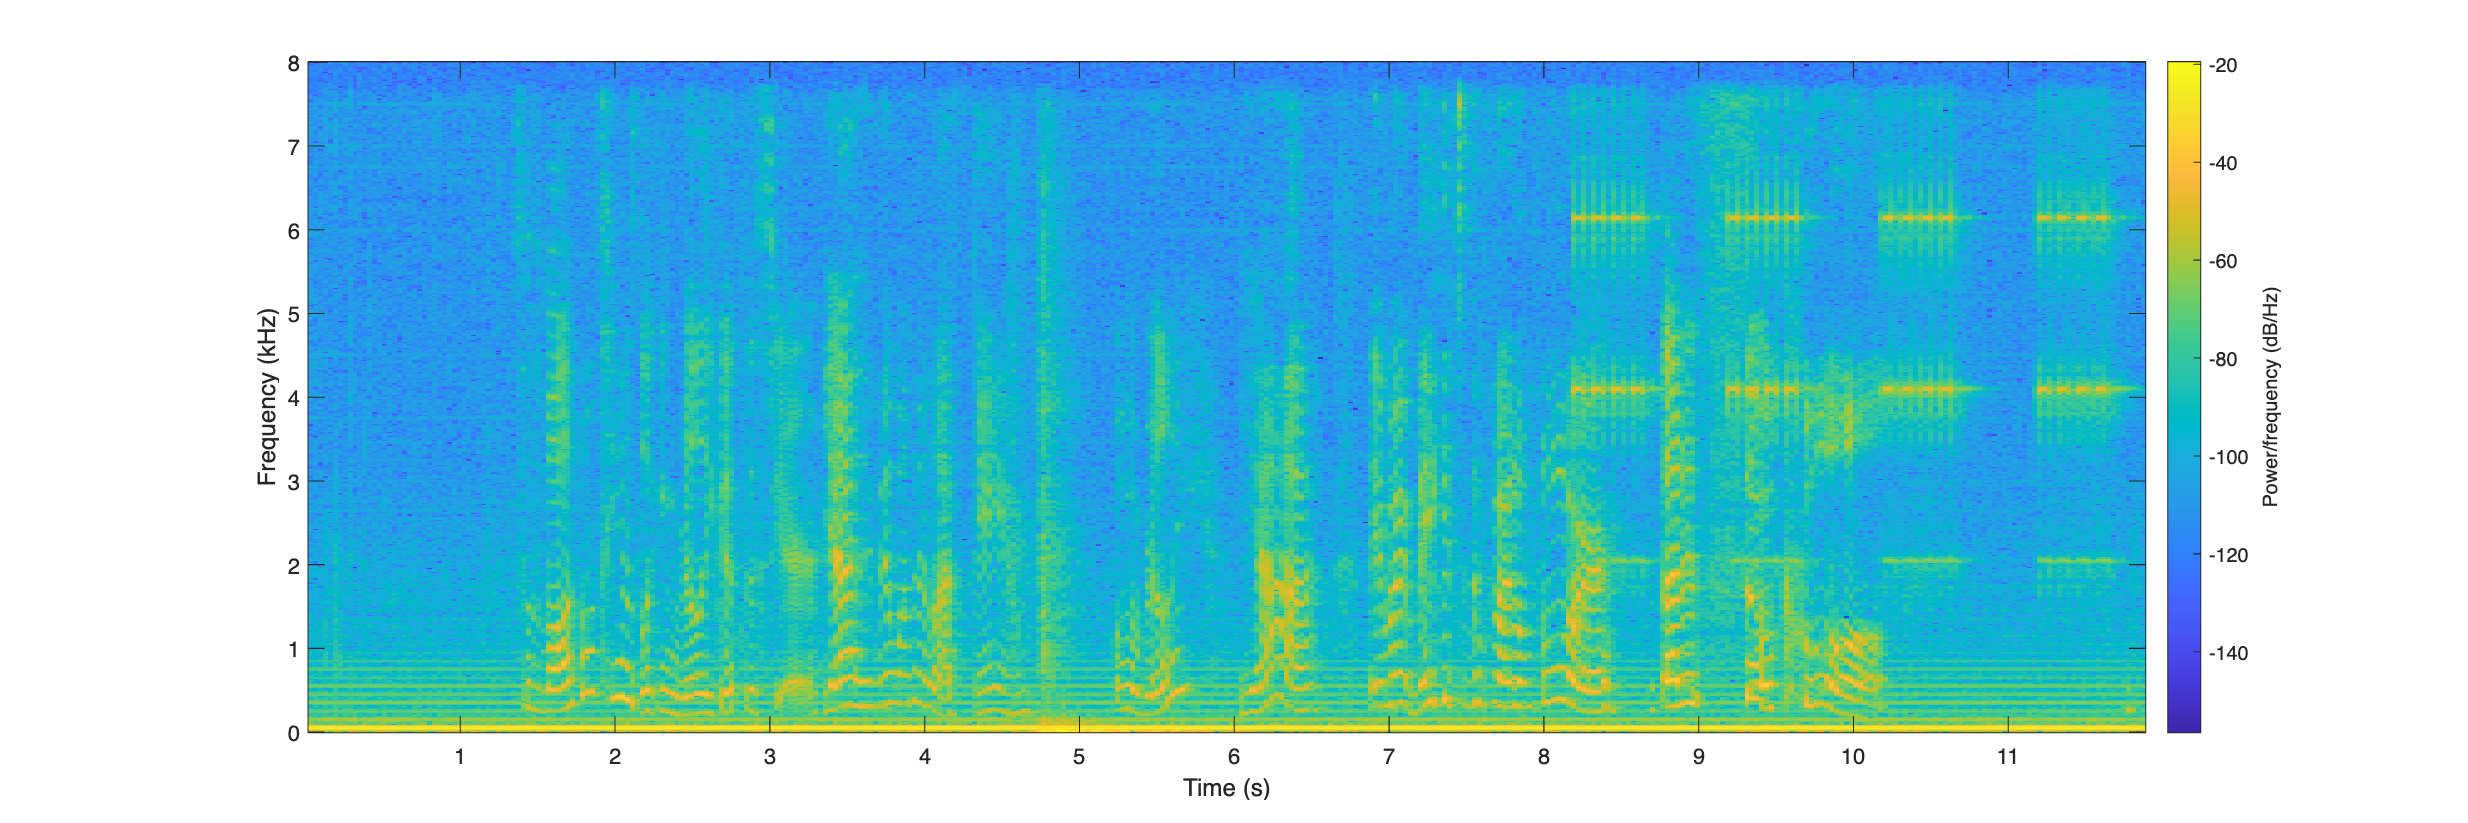

[x, fs] = audioread('noised.wav');

win_size = 1024;
figure('Position', [10 10 1200 400]);
spectrogram(x, blackman(win_size), win_size/2, [], fs, 'yaxis')

## Przygotowanie i analiza charakterystyki filtrów

% częstotliwość odcięcia
fc = 555;
% stromość zbocza
fb = 100;

F_low = f_lowpass(fc, fb, fs);

   640



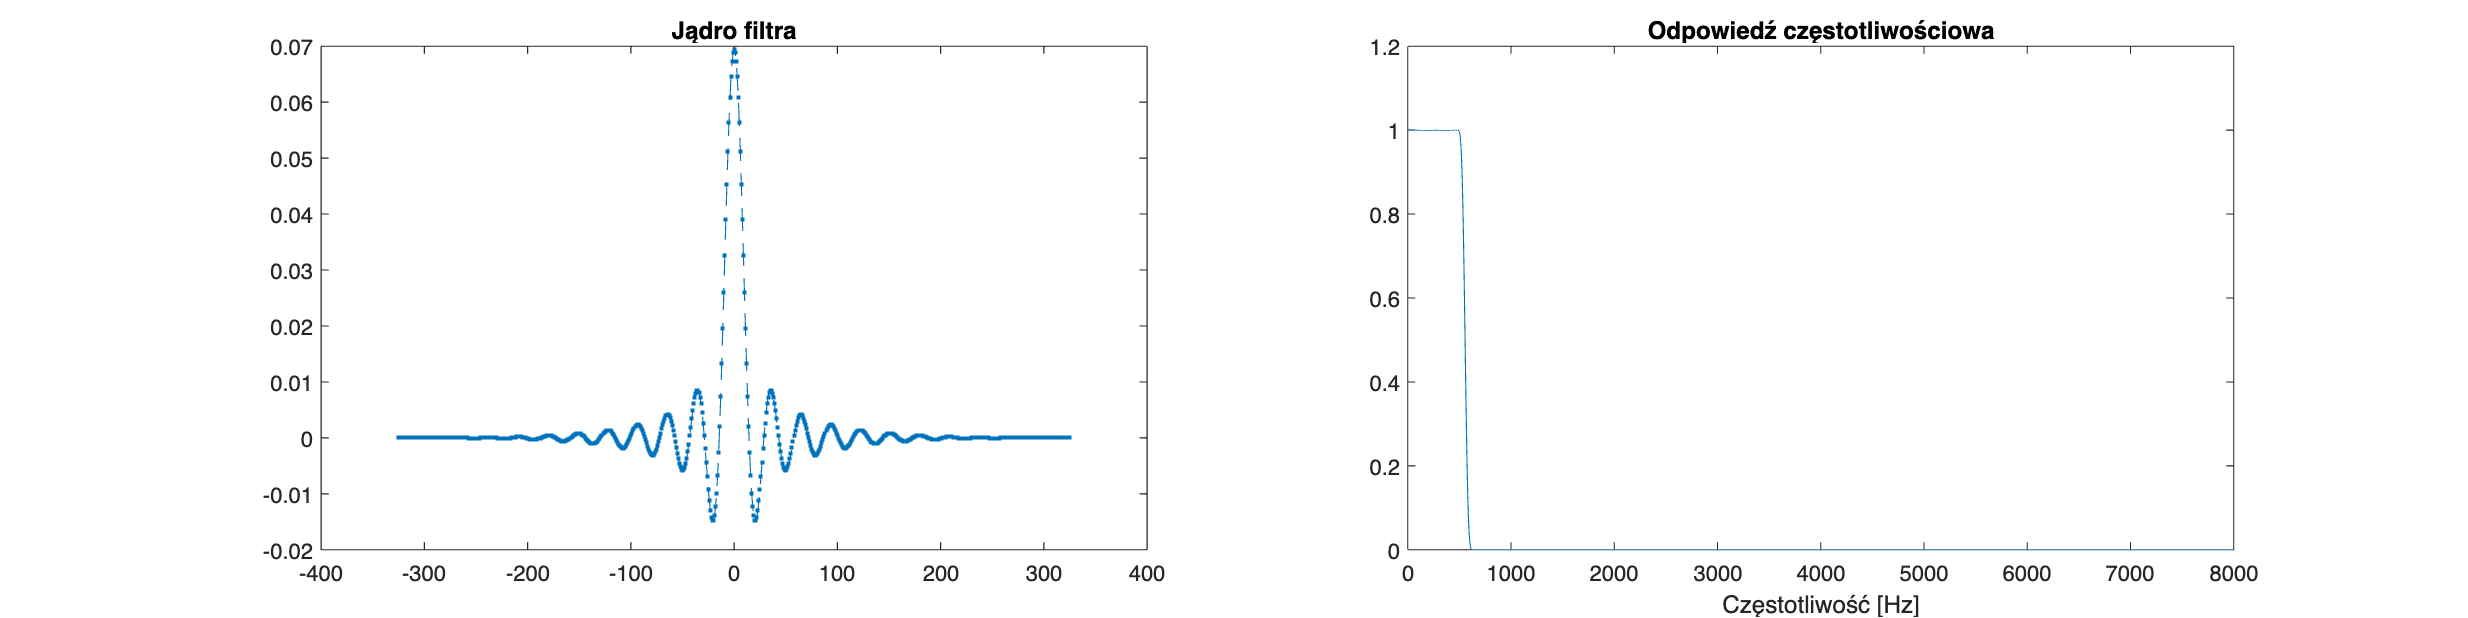

filtstat(F_low, fs);

F_high = f_highpass(fc, fb, fs);

   640



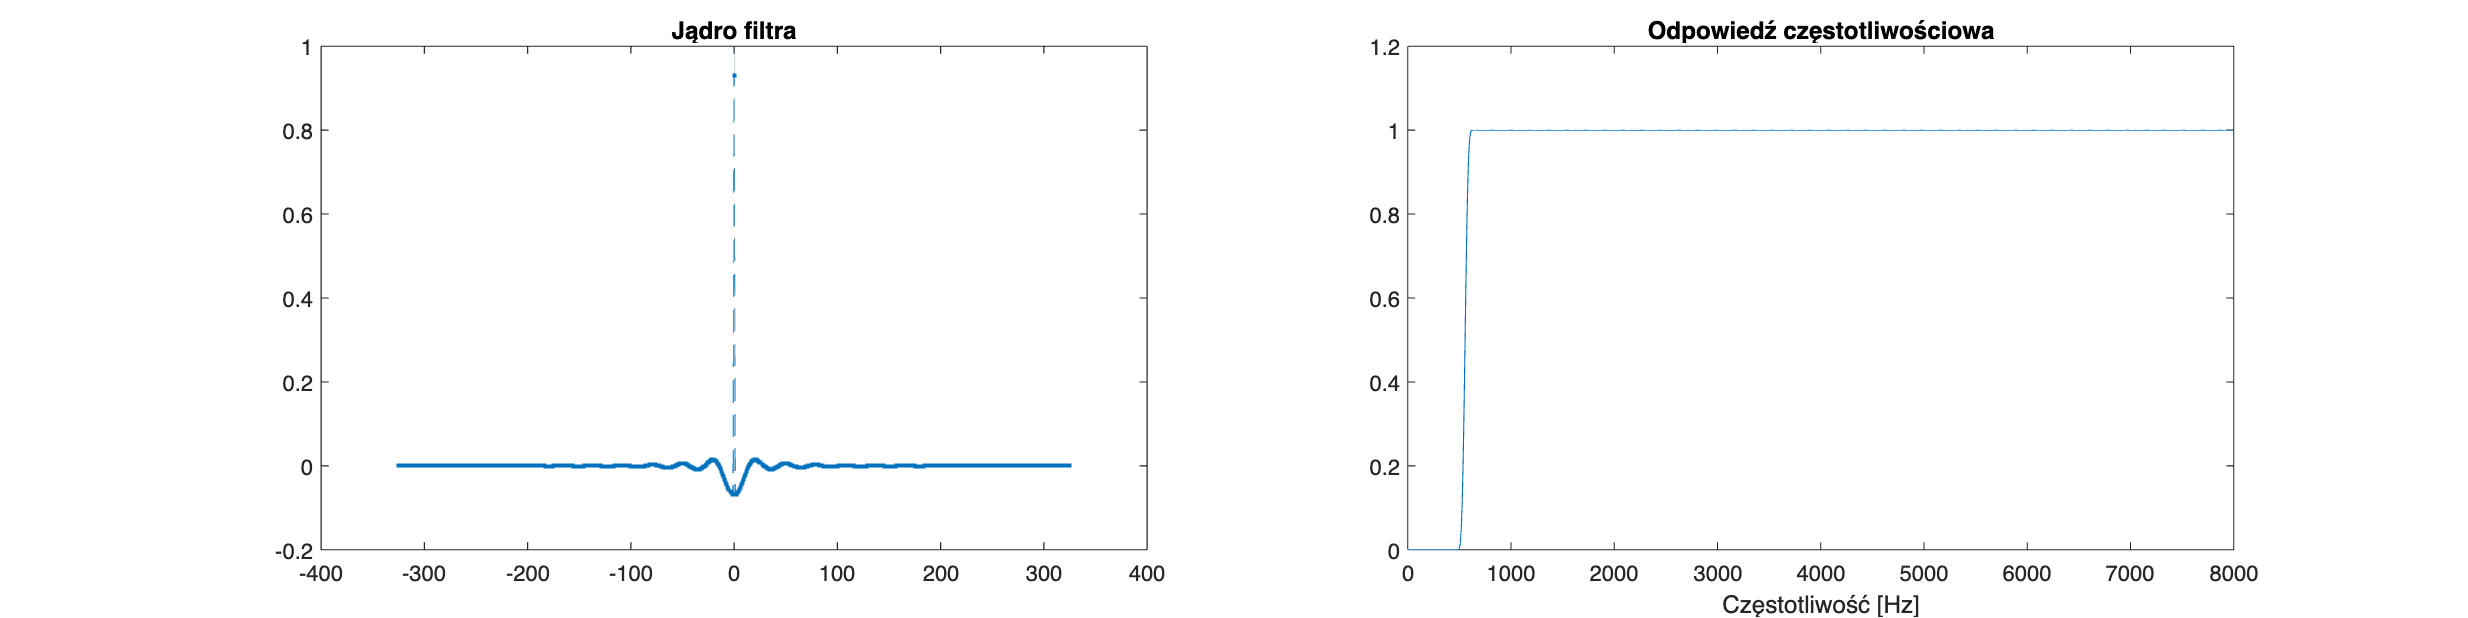

filtstat(F_high, fs);

fl = 500;
fh = 3500;

fl1 = 1800; fh1 = 2200;
fl2 =  3500; fh2 = 4600;
fl3 =  5200; fh3 = 8000;
F_band = f_bandpass(fl, fh, fb, fs);

   640

   640



F1_band  = f_bandpass(fl1, fh1, fb, fs);

   640

   640



F2_band  = f_bandpass(fl2, fh2, fb, fs);

   640

   640



F3_band  = f_bandpass(fl3, fh3, fb, fs);

   640

   640



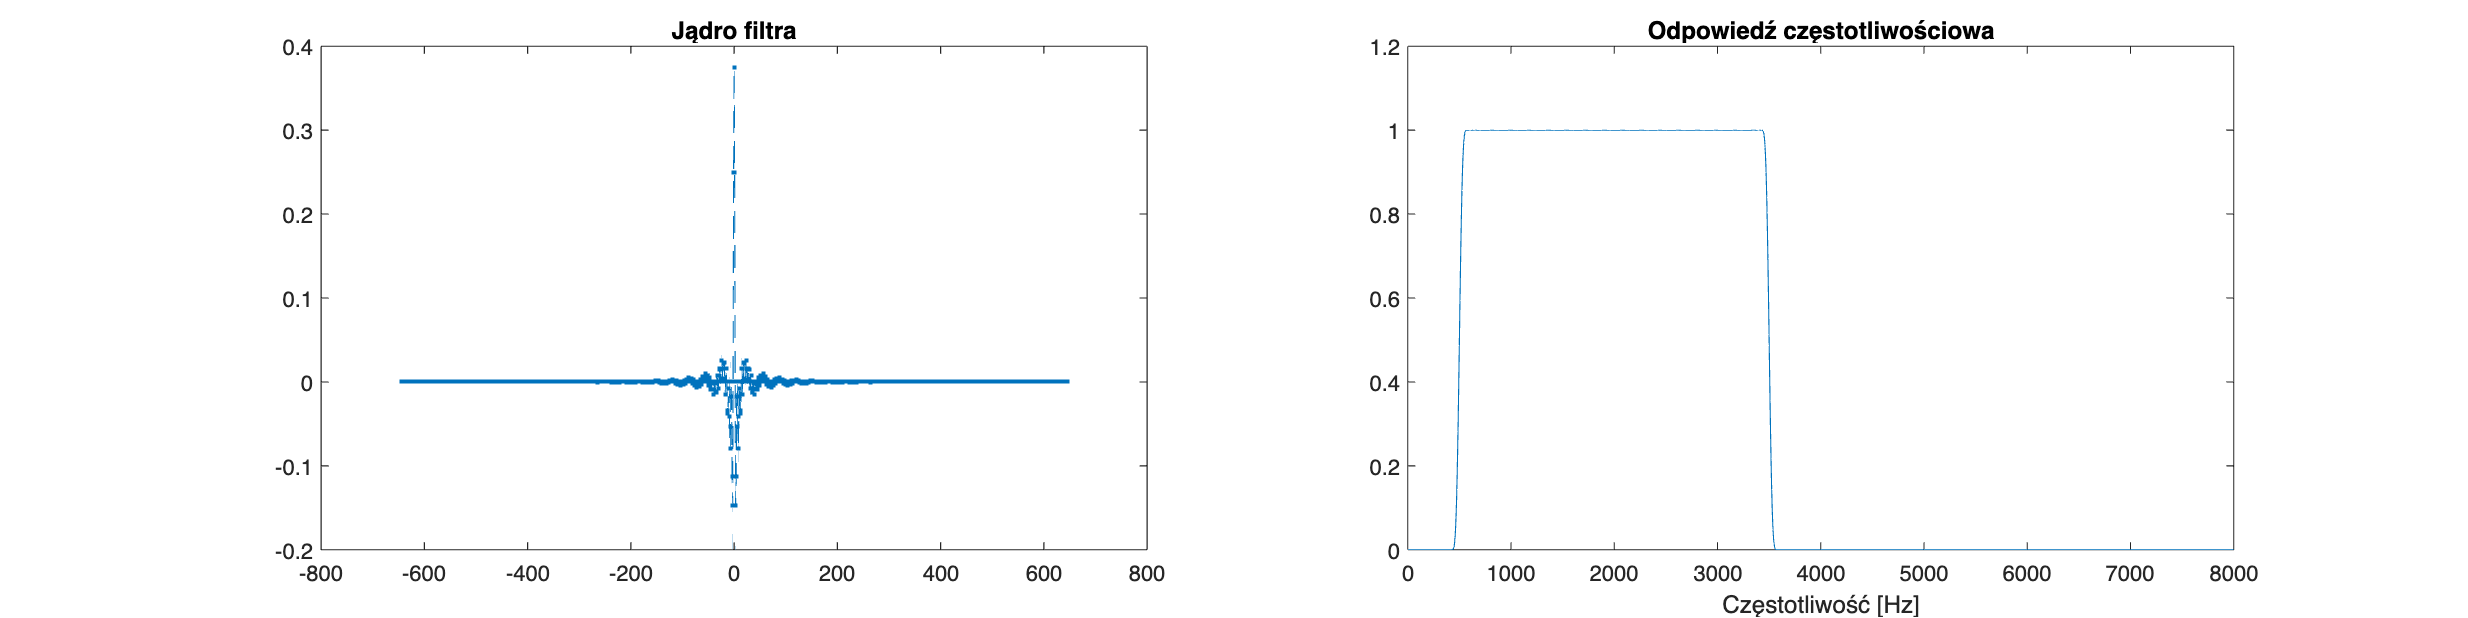

filtstat(F_band, fs);

## Filtracja sygnału

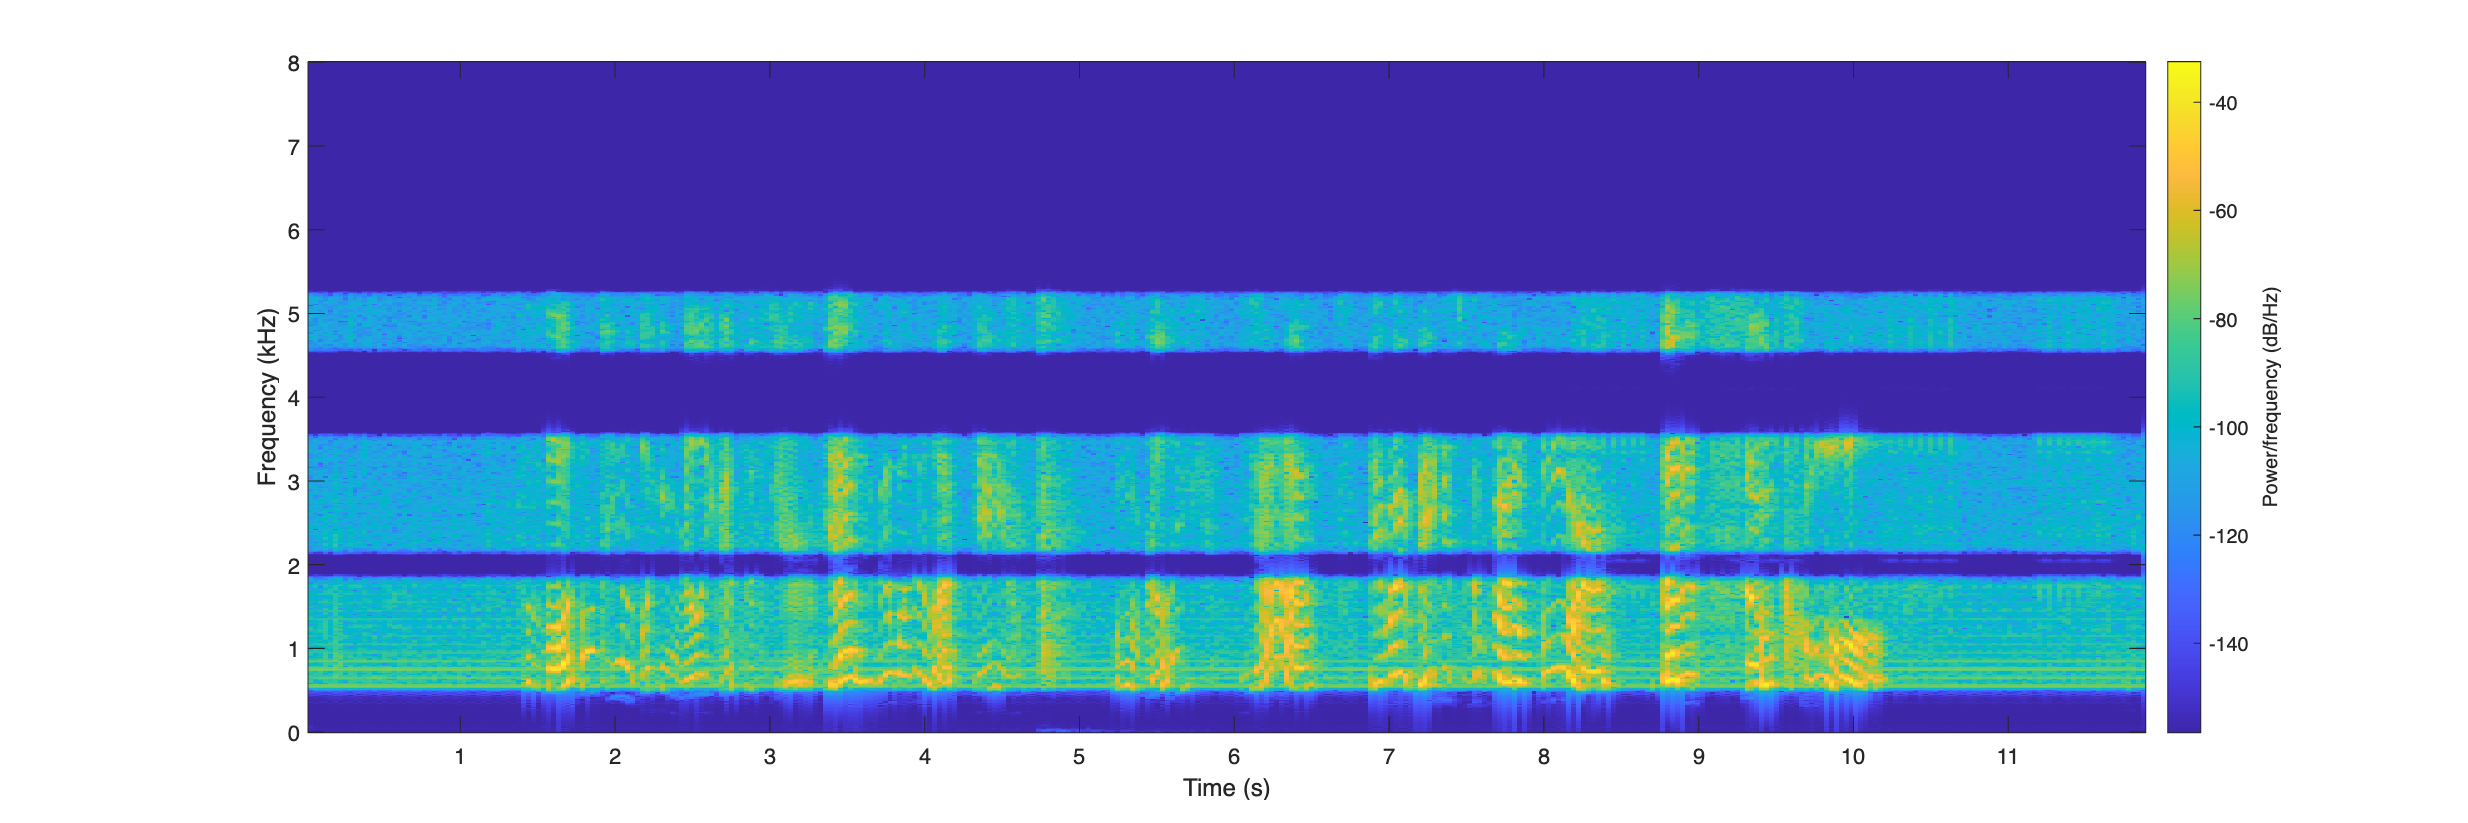

% x_filtered = conv(x, F_low, 'same'); % + conv(x, F_high, 'same') + conv(x, F_band, 'same') + ...
x_filtered =  conv(x, F_high, 'same') - conv(x, F1_band, 'same') - conv(x, F2_band, 'same') - conv(x, F3_band, 'same');
% x_filtered =  conv(x, F_band, 'same') - conv(x, F1_band, 'same');


win_size = 1024;
figure('Position', [10 10 1200 400]);
spectrogram(x_filtered, blackman(win_size), win_size/2, [], fs, 'yaxis')

## Odtworzenie przefiltrowanego sygnału

sound(x_filtered, fs);

## Zapis pliku wyjściowego

audiowrite('output.wav', x_filtered, fs);

## Implementacja filtrów

### Argumenty:

- fc - częstotliwość graniczna (Hz)

- fl, fh - częstotliwości graniczne filtra pasmowego (Hz)

- fb - szerokość pasma przejściowego (Hz)

- fs - częstotliwość próbkowania sygnału filtrowanego (Hz)

function F = f_lowpass(fc, fb, fs)
    % F = ones(1,3) / 3;
  
    fc = fc/fs;
    fb = fb/fs;

    M = round(2/fb)*2;
    disp(M);
    h = zeros(1,M+1);

    for i = 0:M
        if i == M/2
            h(i+1) = 2*pi*fc;
            continue
        end
        h(i+1) = sin(2*pi*fc*(i-M/2))/(i-M/2)*(0.42-0.5*cos(2*pi*i/M)+0.08*cos(4*pi*i/M));
    end

    F = h/sum(h);
    

      
end

function F = f_highpass(fc, fb, fs)
    % F = [-1 0 1];
    F = f_lowpass(fc, fb, fs);
    f_zeros = zeros(1,length(F));
    f_zeros(round(length(f_zeros)/2)) = 1;
    F = -F + f_zeros;
end

function F = f_bandpass(fl, fh, fb, fs)
    % F = f_lowpass(fh, fb, fs) + f_highpass(fl, fb, fs);
    F = conv(f_lowpass(fh, fb, fs), f_highpass(fl, fb, fs));
end

## Funkcje wyświetlające dane

function filtstat(f, fs)
    nfft = 10000;
    
    f_ex = zeros(1, nfft);
    f_ex(1:size(f, 2)) = f;
        
    y = fft(f_ex);
    f_base = linspace(0, fs/2, nfft/2+1);
    amp = abs(y(1:nfft/2+1));
    phase = angle(y(1:nfft/2+1));
    
    figure('Position', [10 10 1200 300]);
    subplot(121);
    f_pad = [zeros(1, 5), f, zeros(1, 5)];
    t_pad = (1:length(f_pad)) - round(length(f_pad) / 2);
    plot(t_pad, f_pad, '.--');
    title("Jądro filtra");
    subplot(122);
    plot(f_base, amp);
    title("Odpowiedź częstotliwościowa");
    xlabel("Częstotliwość [Hz]");
end